# Laboratorio di Automatica (prova del 27 Agosto 2018)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

August 27, 2018

Dept. of Information Engineering, University of Padova

## Esercizio 1

Si consideri un sistema del primo ordine con zero, a tempo continuo:


$$R(s) = \frac{s}{\tau s+1}$$
  

con $\tau=5$.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1) Discretizzare il sistema utilizzando i metodi di *Eulero in avanti*, *Eulero all'indietro*, *Trasformazione bilineare di Tustin *per un generico tempo di campionamento $T$. Discutere la stabilità dei sistemi al variare di $T \in [0.1,1]s$, determinando l'eventuale valore limite per $T$. Si visualizzi in una figura come si spostano i poli del sistema al variare di $T$.

*Soluzione*.

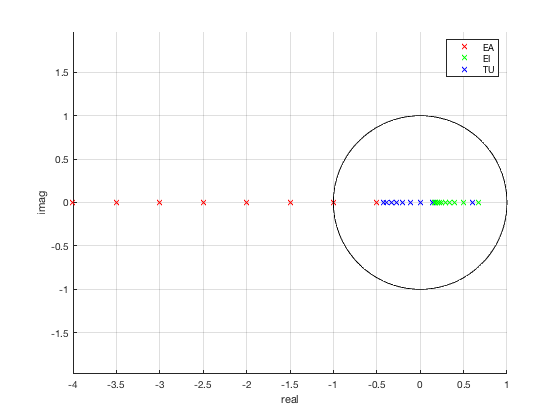

%    parameters
tau = 0.2;

%    plant tf
sysRc = tf([1 0], [tau, 1]);

%    discretization
T = (.1:.1:1);

figure(1)
hold on; grid on; axis equal;

for i = 1:length(T)
    Ti=T(i);
    %    EA
    sysRdEA = tf([1 -1], [tau Ti-tau] ,Ti);
    plot(real(pole(sysRdEA)),imag(pole(sysRdEA)),'rx')
    %    EI
    sysRdEI = tf([1 -1], [Ti+tau -tau] ,Ti);
    plot(real(pole(sysRdEI)),imag(pole(sysRdEI)),'gx')
    %    TU
    sysRdTU = tf(2*[1 -1], [2*tau+Ti -2*tau+Ti] ,Ti);
    plot(real(pole(sysRdTU)),imag(pole(sysRdTU)),'bx')
end

th = 0:pi/100:2*pi; plot(cos(th), sin(th), 'k')
xlabel('real'); ylabel('imag')

legend('EA', 'EI', 'TU');

2) Scelto un tempo di campionamento pari a $T=0.5s$, si confrontino graficamente le risposte all'impulso dei sistemi discretizzati che risultano stabili con la risposta all'impulso del sistema a tempo continuo.

Si discretizzi inoltre il sistema a tempo continuo in modo da preservare la risposta all'impulso, e se ne verifichi il risultato.

*Soluzione*.

Confronto delle risposte all'impulso del sistema a tempo continuo e dei sistemi discretizzati (BIBO stabili).

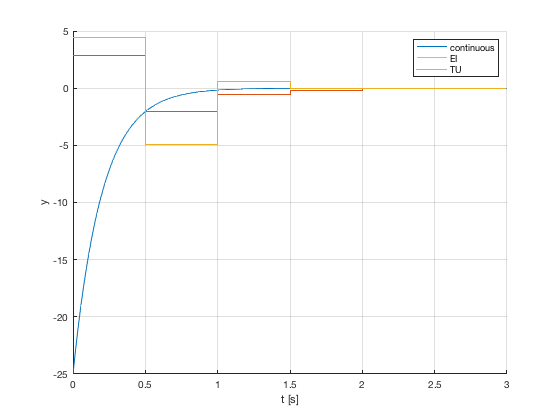

%   sampling time
Ti = 0.5;

%    EA (not BIBO stable - removed from analysis)
%    sysRdEA = tf([1 -1], [tau Ti-tau] ,Ti);

%    EI
sysRdEI = tf([1 -1], [Ti+tau -tau] ,Ti);

%    TU
sysRdTU = tf(2*[1 -1], [2*tau+Ti -2*tau+Ti] ,Ti);

%   impulse responses
Tfinal = 3;
[yRc, tc] = impulse(sysRc, Tfinal);
%[yRdEA, tdEA] = impulse(sysRdEA, Tfinal);
[yRdEI, tdEI] = impulse(sysRdEI, Tfinal);
[yRdTU, tdTU] = impulse(sysRdTU, Tfinal);

%    plot responses
figure;
grid on; 
hold on;
xlabel('t [s]'); ylabel('y')
plot(tc, yRc)
stairs(tdEI, yRdEI)
stairs(tdTU, yRdTU)
legend('continuous', 'EI', 'TU');

Confronto delle risposte all'impulso del sistema a tempo continuo e del sistema discretizzato con metodo dell'invarianza all'impulso.

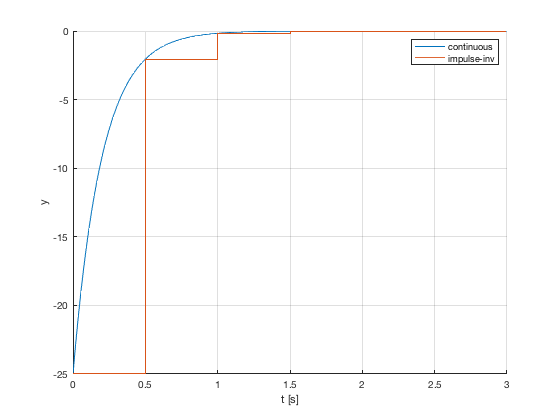

%    impulse invariance discretization
sysRdI = c2d(sysRc,Ti,'impulse');

%    impulse response
[yRdI, td] = impulse(sysRdI, Tfinal);

%   plot responses
figure;
grid on; hold on;
xlabel('t [s]'); ylabel('y')
plot(tc, yRc)
stairs(td, yRdI)
legend('continuous', 'impulse-inv');

3) Scelto un tempo di campionamento pari a $T=0.5s$, si traccino i diagrammi di Bode della funzione a tempo continuo e della funzione discretizzata con il metodo di Tustin. Si calcolino attenuazione (in dB) e sfasamento (in gradi) alla pulsazione $\bar \omega = \omega_N/2$, dove $\omega_N$ è la pulsazione di Nyquist.

*Soluzione*.

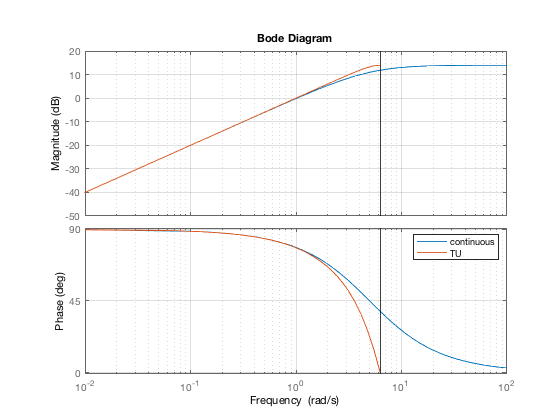

%   Bode plot
Ti=0.5;

%    TU
sysRdTU = tf(2*[1 -1], [2*tau+Ti -2*tau+Ti] ,Ti);

%    Bode plots
figure;
bode(sysRc, sysRdTU)
grid on
legend('continuous', 'TU')


%   attenuation and phase-lag at the desired frequency
wN = pi/Ti;
wbar = wN/2;

[Mc,Pc] = bode(sysRc,wbar);
[MdTU,PdTU] = bode(sysRdTU,wbar);

disp('Attenuation [dB]:')

Attenuation [dB]:


deltaM = 20*log10(MdTU)-20*log10(Mc)

deltaM = 1.3948


disp('Phase-lag [deg]:')

Phase-lag [deg]:


deltaP = PdTU-Pc

deltaP = -6.5179

4) Si corregga la distorsione di cui al punto precedente attraverso la discretizzazione di Tustin con *prewarping* delle frequenze e si verifichi il risultato confrontando le due discretizzazioni di Tustin con la funzione a tempo continuo:

- mediante visualizzazione dei diagrammi di Bode

- mediante visualizzazione delle risposte temporali ad un segnale forzante sinusoidale (*Nota*: per ottenere la risposta temporale, si utilizzi la routine lsim del CST)

Cosa capita a basse frequenze (ad es. $\omega_l = \omega_N/100$)?

*Soluzione*.

Analisi alla frequenza $\bar \omega = \omega_N/2$ :

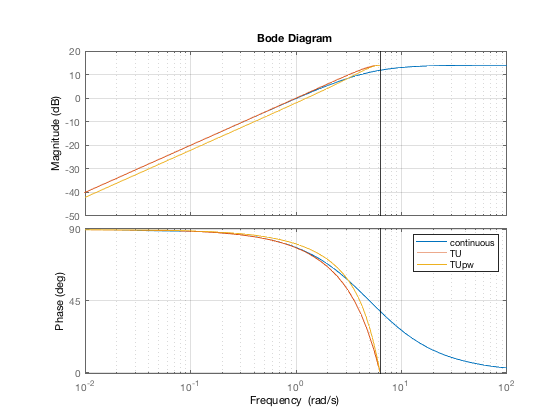

%    frequency-prewarped Tustin discretization
sysRdTU = c2d(sysRc, Ti, 'Tustin');
opt = c2dOptions('Method', 'Tustin', 'PrewarpFrequency', wbar);
sysRdTUpw = c2d(sysRc, Ti, opt);

%    plot Bode plots
figure;
bode(sysRc,sysRdTU,sysRdTUpw)
grid on
legend('continuous', 'TU', 'TUpw');

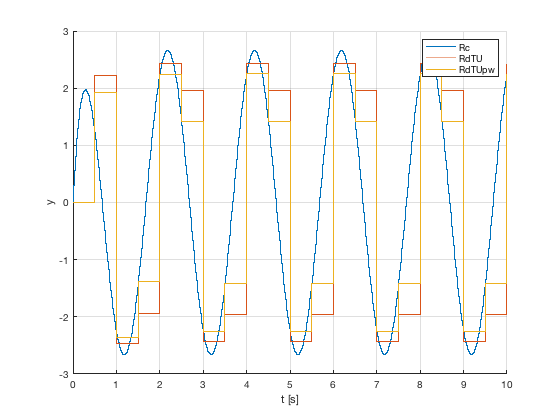


%    time responses
tc = 0:.01:10;
u = sin(wbar*tc);
yRc = lsim(sysRc, u, tc);

t = 0:Ti:10;
u = sin(wbar*t);
yRdTU = lsim(sysRdTU,u,t);
yRdTUpw = lsim(sysRdTUpw,u,t);

%    plot time responses
figure
hold on; grid on;
xlabel('t [s]'); ylabel('y');
stairs(tc,yRc)
stairs(t,yRdTU)
stairs(t,yRdTUpw)
legend('Rc', 'RdTU', 'RdTUpw')

Analisi alla frequenza $\omega_l = \omega_N/100$ :

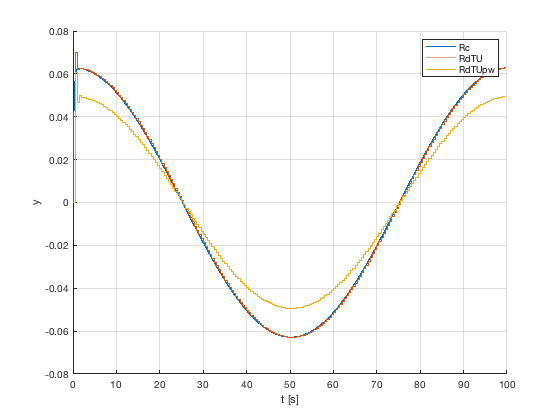


wl = wN/100;
tc = 0:.01:100;
u = sin(wl*tc);
yRc = lsim(sysRc,u,tc);
t = 0:Ti:100;
u = sin(wl*t);
yRdTU = lsim(sysRdTU,u,t);
yRdTUpw = lsim(sysRdTUpw,u,t);

figure
hold on; grid on;
xlabel('t [s]'); ylabel('y');
stairs(tc,yRc)
stairs(t,yRdTU)
stairs(t,yRdTUpw)
legend('Rc', 'RdTU', 'RdTUpw')